# Part 6: Cheaters at range

%Temporary / diagnostic changes

%change amount of initial enzyme
%args.p6.v.initenzyme = args.p6.v.initenzyme * 1000

%remove enzyme decay
%args.p6.v.enzdecayperhour = 0;

args.p6.v.drainatedges = false;

args.p6.v.maxcycles = 1500;
args.p6.v.timestep = 4;

args.p6.v.alpha = exp(-2);

args.p6.v.numExRxnSubsteps = 1;

%Generate/load the data
if runPart6
    
    args.p6.v_default = v_default;
    args.p6.distances = [0 .1 .2 .3 .4 .5 1.0 1.5 2.0]; %in cm
    args.p6.distances = [0 .1];
    args.p6.distances = .1;
    args.p6.distances = [0 .1 .2 .5 1];
    args.p6.distances = [0 .1 .2];
    
    dat6 = part6_generation(args.p6)
else
    if ~exist('dat6','var')
        load([datadir '\dat6.mat']);
    end
end

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51 tRNA(Lys) [cytoplasm] + 22 tR

Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp
Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp
Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


dat6 = 3×28 table
       timestep               t           cellulose_total      cellulose_coord         glc_total            glc_coord            enz_total            enz_coord           etoh_total           etho_coord         producer_total      producer_coord       cheater_total       cheater_coord      cellulose_delta       glc_delta          enz_delta         etoh_delta        alpha     decayrate    costfactor    kcat_cel    km_cel    vmax_glc    km_glc    diff_enz    diff_glc    distance
    _____________

%Biomass time series
figure();

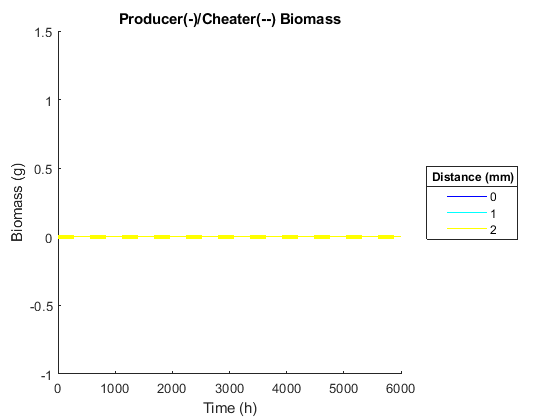

[nrows,~] = size(dat6);
hold on;
colors = jet(nrows);
for i = 1:nrows
    plot(dat6.t{i},dat6.producer_total{i},'-','color',colors(i,:),'linewidth',1,'displayname',num2str(dat6.distance(i)));
    plot(dat6.t{i},dat6.cheater_total{i},'--','color',colors(i,:),'linewidth',3,'HandleVisibility','off');
end
hold off;
leg = legend('location','eastoutside');
title(leg,'Distance (mm)');
title('Producer(-)/Cheater(--) Biomass')
ylabel('Biomass (g)')
xlabel('Time (h)')

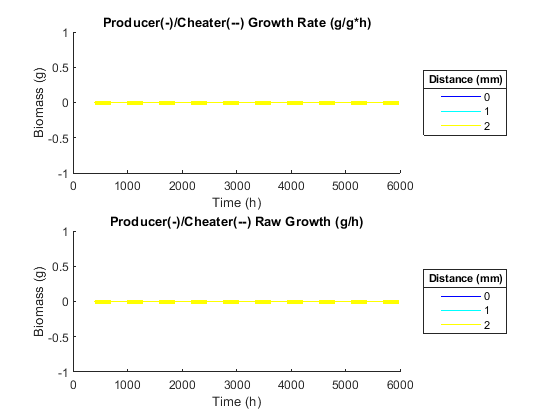

%growth rate time series
%as a function of current biomass in g per g*h
windowsize = 100; %smooth the plot by averaging over n timesteps
figure()
subplot(2,1,1)
[nrows,~] = size(dat6);
hold on;
colors = jet(nrows);
for i = 1:nrows
    dt = dat6.t{i}(2) - dat6.t{i}(1);
    pro = dat6.producer_total{1};
    deltapro = pro(2:end) - pro(1:end-1);
    deltapro = deltapro / dt;
    deltapro_rel = deltapro ./ pro(1:end-1);
    deltapro_rel = arrayfun(@(x) mean(deltapro_rel(x:x+(windowsize-1))),1:size(deltapro_rel)-windowsize+1);
    plot(dat6.t{i}(windowsize:end-1),deltapro_rel,'-','color',colors(i,:),'linewidth',1,'displayname',num2str(dat6.distance(i)));
    che = dat6.cheater_total{1};
    deltache = che(2:end) - che(1:end-1);
    deltache = arrayfun(@(x) mean(deltache(x:x+(windowsize-1))),1:size(deltache)-windowsize+1);
    deltache_rel = deltache ./ che(1:end-1);
    plot(dat6.t{i}(windowsize:end-1),deltache_rel,'--','color',colors(i,:),'linewidth',3,'HandleVisibility','off');
end
hold off;
leg = legend('location','eastoutside');
title(leg,'Distance (mm)');
title('Producer(-)/Cheater(--) Growth Rate (g/g*h)')
ylabel('Biomass (g)')
xlabel('Time (h)')
%raw growth in g per h
subplot(2,1,2)
hold on;
for i = 1:nrows
    dt = dat6.t{i}(2) - dat6.t{i}(1);
    pro = dat6.producer_total{1};
    deltapro = pro(2:end) - pro(1:end-1);
    deltapro = deltapro / dt;
    deltapro = arrayfun(@(x) mean(deltapro(x:x+(windowsize-1))),1:size(deltapro)-windowsize+1);
    plot(dat6.t{i}(windowsize:end-1),deltapro,'-','color',colors(i,:),'linewidth',1,'displayname',num2str(dat6.distance(i)));
    che = dat6.cheater_total{1};
    deltache = che(2:end) - che(1:end-1);
    deltache = arrayfun(@(x) mean(deltache(x:x+(windowsize-1))),1:size(deltache)-windowsize+1);
    plot(dat6.t{i}(windowsize:end-1),deltache,'--','color',colors(i,:),'linewidth',3,'HandleVisibility','off');
end
hold off;
leg = legend('location','eastoutside');
title(leg,'Distance (mm)');
title('Producer(-)/Cheater(--) Raw Growth (g/h)')
ylabel('Biomass (g)')
xlabel('Time (h)')

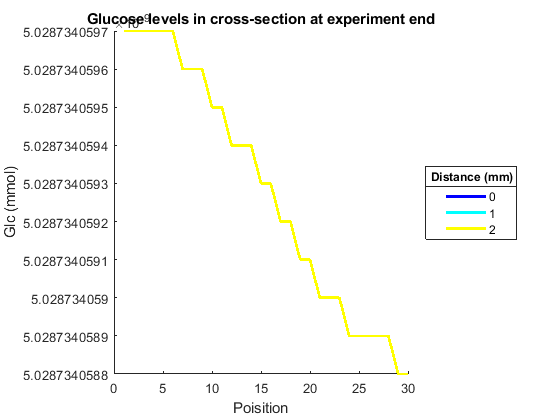


%Glucose levels in a slice at end
figure();
hold on;
for i = 1:nrows
    glc = dat6.glc_coord{i}(6,:,end);
    plot(1:length(glc),glc,'color',colors(i,:),'linewidth',2,'displayname',num2str(dat6.distance(i)));
end
hold off;
leg = legend('location','eastoutside');
title(leg,'Distance (mm)');
xlabel('Poisition');
ylabel('Glc (mmol)');
title('Glucose levels in cross-section at experiment end');

## Part 6b: Turn down diffusibility of enzyme and glc independently and in tandem

if runPart6b
    args.p6.distances = 2; %in cm
    
    args.p6.v.maxcycles = 1000;
    args.p6.v.timestep = 4;
    args.p6.v.alpha = exp(-7);
    args.p6.v.drainatedges = false;
    
    %https://doi.org/10.1080/09593332608618574: "Results showed that De of glucose in the biomass-free agarose 
    %films averaged 6.46±0.21×10−6 cm2 s−1, which is about 5% lower than the average reported De of glucose in
    %water."
    % 6.46e-6 cm^2/s 
    diff_enz0 = args.p6.v.diff_enz;
    diff_glc0 = args.p6.v.diff_glc;
    edifs = [0 1e-7 1e-6 1e-5];
    gdifs = [0 1e-7 1e-6 1e-5];
    edifs = [0 1e-6];
    gdifs = [0 1e-6];
    dat6b = table();
    
    ienz0 = args.p6.v.initenzyme;
    %ienz = [9e-8 9e-6 9e-4];
    ienz = ienz0;
    
    for k = ienz
        args.p6.v.initenzyme = k;
        for i = edifs
            args.p6.v.diff_enz = i;
            for j = gdifs
                args.p6.v.diff_glc = j;
                tmp = part6_generation(args.p6);
                dat6b = vertcat(dat6b,tmp);
            end
        end
    end
    args.p6.v.initenzyme = ienz0;
    args.p6.v.diff_enz = diff_enz0;
    args.p6.v.diff_glc = diff_glc0;
else
    if ~exist('dat6b','var')
        load([datadir '\dat6b.mat']);
    end
end

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51 tRNA(Lys) [cytoplasm] + 22 tR

Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp
produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 t

Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp
produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 t

Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp
produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 t

Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


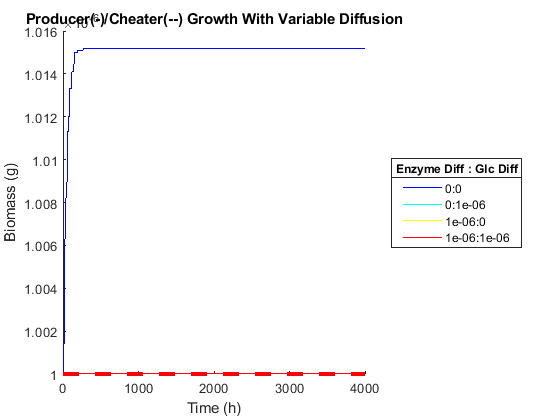

figure();
[nrows,~] = size(dat6b);
hold on;
colors = jet(nrows);
for i = 1:nrows
    plot(dat6b.t{i},dat6b.producer_total{i},'-','color',colors(i,:),'linewidth',1,'displayname',[num2str(dat6b.diff_enz(i)) ':' num2str(dat6b.diff_glc(i))]);
    plot(dat6b.t{i},dat6b.cheater_total{i},'--','color',colors(i,:),'linewidth',3,'HandleVisibility','off');
end
hold off;
leg = legend('location','eastoutside');
title(leg,'Enzyme Diff : Glc Diff');
title('Producer(-)/Cheater(--) Growth With Variable Diffusion')
ylabel('Biomass (g)')
xlabel('Time (h)')

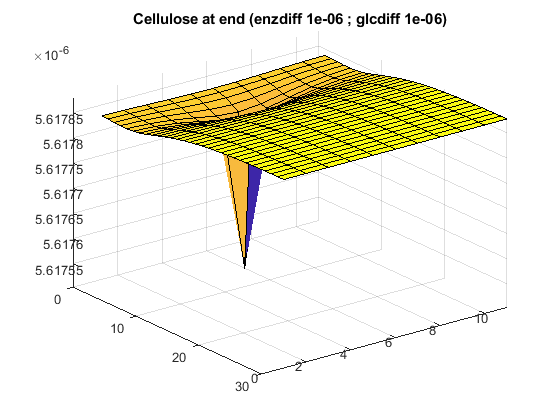

%Plot maps of media components at end
maxglc = max(cellfun(@(x) max(x(:)),dat6b.glc_coord(end)));
maxenz = max(cellfun(@(x) max(x(:)),dat6b.enz_coord(end)));
maxcel = max(cellfun(@(x) max(x(:)),dat6b.cellulose_coord(end)));
mincel = min(cellfun(@(x) min(x(:)),dat6b.cellulose_coord(end)));
minenz = min(cellfun(@(x) min(x(:)),dat6b.enz_coord(end)));
minglc = min(cellfun(@(x) min(x(:)),dat6b.glc_coord(end)));
%toggle which series to show
edif = 1e-6;
gdif = 1e-6;
% edif = 1e-6;
% gdif = 1e-6;
% edif = 1e-7;
% gdif = 1e-7;
% edif = 0;
% gdif = 0;
row = dat6b(dat6b.diff_enz == edif,:);
row = row(row.diff_glc == gdif,:);

%Cellulose
amt = row.cellulose_coord{1};
amt = amt(:,:,end);
% amt = amt - min(amt);
% amt = amt ./ max(amt);
[xdim,ydim] = size(amt);
[X,Y] = meshgrid(1:xdim,1:ydim);
surf(X,Y,amt');
zlim([mincel,maxcel]);
title(['Cellulose at end (enzdiff ' num2str(edif) ' ; glcdiff ' num2str(gdif) ')']);
set(gca,'Ydir','reverse');

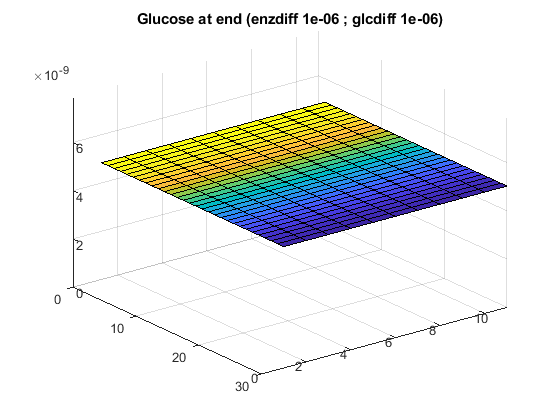


%Glucose
amt = row.glc_coord{1};
amt = amt(:,:,end);
[xdim,ydim] = size(amt);
[X,Y] = meshgrid(1:xdim,1:ydim);
surf(X,Y,amt');
zlim([minglc maxglc]);
title(['Glucose at end (enzdiff ' num2str(edif) ' ; glcdiff ' num2str(gdif) ')']);
set(gca,'Ydir','reverse');

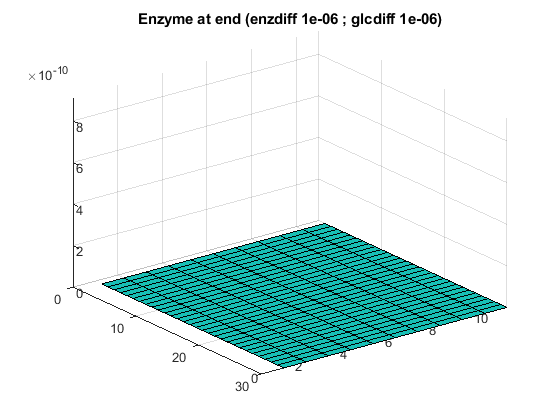


%Enzyme
amt = row.enz_coord{1};
amt = amt(:,:,end);
% amt = amt - min(amt(:));
% amt = amt ./ max(amt);
[xdim,ydim] = size(amt);
[X,Y] = meshgrid(1:xdim,1:ydim);
surf(X,Y,amt');
zlim([minenz maxenz]);
title(['Enzyme at end (enzdiff ' num2str(edif) ' ; glcdiff ' num2str(gdif) ')']);
set(gca,'Ydir','reverse');

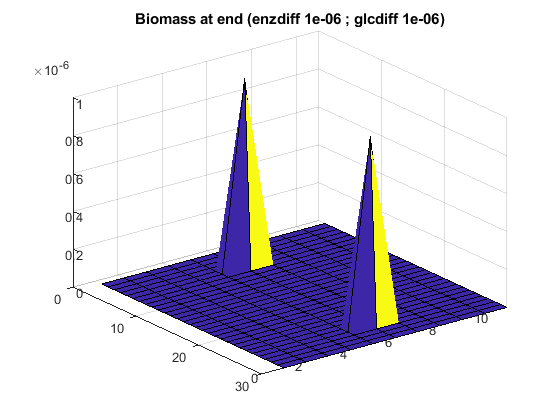

%Biomass
amt = row.cheater_coord{1} + row.producer_coord{1};
amt = amt(:,:,end);
% amt = amt - min(amt(:));
% amt = amt ./ max(amt);
resized = zeros(11,30);
[ax,ay] = size(amt);
for x = 1:ax
    for y = 1:ay
        resized(y,x) = amt(x,y);
    end
end
amt = resized;
[xdim,ydim] = size(amt);
[X,Y] = meshgrid(1:xdim,1:ydim);
surf(X,Y,amt');
% xlim([0 12]);
% ylim([0 21]);
title(['Biomass at end (enzdiff ' num2str(edif) ' ; glcdiff ' num2str(gdif) ')']);
set(gca,'Ydir','reverse');

%Biomass at all values

%note: checking that the initial secreted enzyme amount is higher than the
%minimum concentration (set to 1e-26 as of 3/4/2019)
initmaxenzdelta = args.p6.v.alpha * args.p6.v.initialpop

initmaxenzdelta = 9.1188e-10

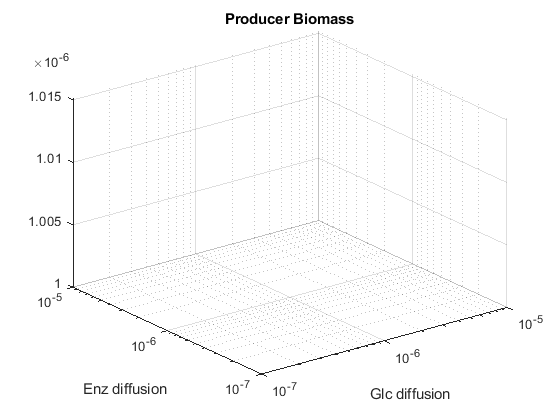


gdifs = unique(dat6b.diff_glc);
edifs = unique(dat6b.diff_enz);
prod = zeros(length(gdifs),length(edifs));
cheat = prod;
for x = 1:length(gdifs)
    for y = 1:length(edifs)
        row = dat6b(dat6b.diff_glc == gdifs(x),:);
        row = row(row.diff_enz == edifs(y),:);
        prod(x,y) = row.producer_total{1}(end);
        cheat(x,y) = row.cheater_total{1}(end);
    end
end
maxbio = max(max(prod(:)),max(cheat(:)));
minbio = min(min(prod(:)),min(cheat(:)));
[X,Y] = meshgrid(gdifs,edifs);
surf(X,Y,prod);
title('Producer Biomass');
xlabel('Glc diffusion');
ylabel('Enz diffusion');
set(gca,'YScale','log');
set(gca,'XScale','log');

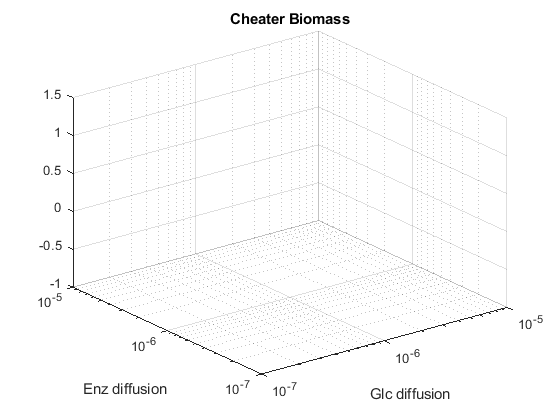

%set(gca,'ZScale','log');
%zlim([minbio maxbio]);

surf(X,Y,cheat);
title('Cheater Biomass');
xlabel('Glc diffusion');
ylabel('Enz diffusion');
set(gca,'YScale','log');
set(gca,'XScale','log');

%set(gca,'ZScale','log');
%zlim([minbio maxbio]);


%Compare vs control: Where the "Producer" doesn't make enzyme
%To see how much of the effect is from the initial enzyme only
%runPart6c = true;
if runPart6c
    args.p6.distances = .2; %in cm
    
    args.p6.v.maxcycles = 150;
    args.p6.v.timestep = 4;
    args.p6.v.drainatedges = false;
    
    ipop0 = args.p6.v.initialpop;
    args.p6.v.initialpop = 1e-10;
    
    diff_enz0 = args.p6.v.diff_enz;
    diff_glc0 = args.p6.v.diff_glc;
    edifs = [0 1e-7 1e-6 1e-5];
    gdifs = [0 1e-7 1e-6 1e-5];
    edifs = 1e-6;
    gdifs = 1e-6;
    dat6c = table();
    layouts = cell(0);
    
    ienz0 = args.p6.v.initenzyme;
    ienz = ienz0;
%     ienz = [9e-8 9e-6 9e-4];
%     ienz = 9e-6;
%     ienz = 5e-5;
%     ienz = 2e-5;
    
    a0 = args.p6.v.alpha;
    alpha = [exp(-9) exp(-7) exp(-5) exp(-3) exp(-1) 0];
    alpha = [exp(-7) exp(-3) 0];
    
    for l = alpha
        args.p6.v.alpha = l;
        for k = ienz
            args.p6.v.initenzyme = k;
            for i = edifs
                args.p6.v.diff_enz = i;
                for j = gdifs
                    args.p6.v.diff_glc = j;
                    [tmp,layout] = part6_generation(args.p6);
                    dat6c = vertcat(dat6c,tmp);
                    layouts = [layouts {layout}];
                end
            end
        end
    end
    args.p6.v.initenzyme = ienz0;
    args.p6.v.diff_enz = diff_enz0;
    args.p6.v.diff_glc = diff_glc0;
    args.p6.v.alpha = a0;
    args.p6.v.initialpop = ipop0;
else
    if ~exist('dat6c','var')
        load([datadir '\dat6c.mat']);
    end
end

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51 tRNA(Lys) [cytoplasm] + 22 tR

Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp
produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 t

Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp
produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 2670 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	2670 adp[c] + 100 tRNA(Ala) [cytoplasm] + 37 t

Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


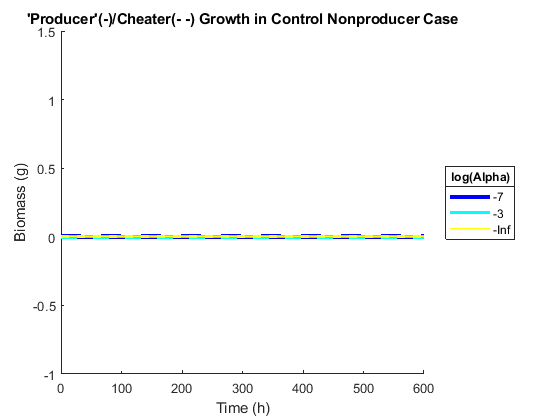

figure();
[nrows,~] = size(dat6c);
hold on;
colors = jet(nrows);
for i = 1:nrows
    plot(dat6c.t{i},dat6c.producer_total{i},'-','color',colors(i,:),'linewidth',nrows+1-i,'displayname',num2str(log(dat6c.alpha(i))));
    plot(dat6c.t{i},dat6c.cheater_total{i},'--','color',colors(i,:),'linewidth',nrows+2-i,'HandleVisibility','off');
end
hold off;
leg = legend('location','eastoutside');
title(leg,'log(Alpha)');
title('''Producer''(-)/Cheater(- -) Growth in Control Nonproducer Case')
ylabel('Biomass (g)')
xlabel('Time (h)')

%DIAGNOSTIC
%confirm that enzyme is being produced
run_diagnostic = false;
if run_diagnostic
    args.p6 = args.default;
    args.p6.model = model_default;
    args.p6.v.spaceWidth = 1;
    args.p6.v.initcellulose = args.default.v.initcellulose / 100; %other experiments are 100ml, this is 1ml grid cells
    args.p6.distances = 2;
    args.p6.v.writefluxlog = true;
    args.p6.v.timestep = 2;
    args.p6.v.maxcycles = 2;
    args.p6.v.alpha = exp(-7);
    args.p6.v.initenzyme = 10;
    args.p6.v.diff_enz = 0;
    [dat6diag,layouts] = part6_generation(args.p6)
    
    fluxes = parseFluxLog([args.p6.v.filepath '\log_flux.m']);
    
end

if exist('dat6diag','var')
    enzmodel = layouts{1}.models{1};
    enzrxn = stridx('EX_enzyme[e]',enzmodel.rxns);
    enzfluxes = fluxes(fluxes.rxn == enzrxn,:)
    prodfluxes = fluxes(fluxes.rxn == stridx('produce_enzyme',enzmodel.rxns),:)
end